%Obtain the first 13 MFCC, delta MFCC, and delta-delta MFCC features for 
% the first utterance recorded in question 2 using the method described 
% in the class with 26 mel-filters, window length of 25 ms, and window 
% shift of 10 ms. Use T=2 for calculating the delta and delta-delta 
% coefficients, and α=0.9 for pre-emphasis. You should explain the 
% code for MFCC computation if asked during evaluation.

% Short time analysis code
clear all
close all
clc

% recording audio 
fs = 16000;
NumSeconds = 5;
NumBits_quant = 16;
Num_channels = 1; % mono 1 channel, 2 for stereo


% calculate MFCC and Deltas for all frames
[speech_vowels, fs] = audioread('abhishek_aiu.wav');
speech_vowels = speech_vowels(floor(0.5*fs):floor(3*fs));
speech = speech_vowels;
WL = 25;
WS = 5;



WL_samp = round(WL*0.001*fs);
WS_Samp = round(WS*0.001*fs);
Num_frames = round(  (length(speech)-WL_samp)/WS_Samp );
MFCC_All = zeros(Num_frames, 13);
N_filters = 26;
N_FFT = 512;
speech = speech(2:end) - 0.9*speech(1:end-1);


for i=1:Num_frames
    startsamp = (i-1)*WS_Samp+1;
    EndSamp = startsamp+WL_samp-1;
    CurrSpeech  = speech(startsamp :EndSamp);
    [MFCC_All(i, :), ~, ~] =  calc_MFCC(CurrSpeech, N_filters, N_FFT, fs);
     
    % calculating delta and delta-delta coefficients
    
    

end


delta = zeros(Num_frames, 13);
for i=3:Num_frames-2
    delta(i,:) = ( (MFCC_All(i-1,:) - MFCC_All(i+1,:))+ 2 * (MFCC_All(i-2,:) - MFCC_All(i+2,:)) )/10;
end

delta_delta = zeros(Num_frames, 13);
for i=5:Num_frames-4
    delta_delta(i,:) = ( (delta(i-1,:) - delta(i+1,:))+ 2 * (delta(i-2,:) - delta(i+2,:)) )/10;
end


% part a: 
a_midpoint = 0.4813; % in sec obtained from the plot
i_midpoint = 1.179;
u_midpoint = 1.915;
alpha = 0.9;

a_midpoint_sample = round(a_midpoint*fs);
i_midpoint_sample = round(i_midpoint*fs);
u_midpoint_sample = round(u_midpoint*fs);

half_wideband_windwolen = round(30*0.001*fs/2);
sig = speech_vowels(a_midpoint_sample-half_wideband_windwolen:a_midpoint_sample+half_wideband_windwolen);
sig = sig/max(abs(sig));
% preemphasis
sig = sig(2:end) - alpha*sig(1:end-1);

[MFCC_a, logFout_a, logFfreq_a] = calc_MFCC(sig, N_filters, N_FFT, fs);
[MFCC_a_40, logFout_a_40, logFfreq_a_40] = calc_MFCC(sig, 40, N_FFT, fs);

half_wideband_windwolen = round(30*0.001*fs/2);
sig = speech_vowels(i_midpoint_sample-half_wideband_windwolen:i_midpoint_sample+half_wideband_windwolen);
sig = sig/max(abs(sig));
% preemphasis
sig = sig(2:end) - alpha*sig(1:end-1);

[MFCC_i, logFout_i, logFfreq_i] = calc_MFCC(sig, N_filters, N_FFT, fs);
[MFCC_i_40, logFout_i_40, logFfreq_i_40] = calc_MFCC(sig, 40, N_FFT, fs);

half_wideband_windwolen = round(30*0.001*fs/2);
sig = speech_vowels(u_midpoint_sample-half_wideband_windwolen:u_midpoint_sample+half_wideband_windwolen);
sig = sig/max(abs(sig));
% preemphasis
sig = sig(2:end) - alpha*sig(1:end-1);

[MFCC_u, logFout_u, logFfreq_u] = calc_MFCC(sig, N_filters, N_FFT, fs);
[MFCC_u_40, logFout_u_40, logFfreq_u_40] = calc_MFCC(sig, 40, N_FFT, fs);


% calculate the MFCC distance
%  /a, i/ dist
dist_ai = ( 10/log(10) )  *   sqrt( 2 *( sum( ( MFCC_a(2:end)-MFCC_i(2:end) ).*( MFCC_a(2:end)-MFCC_i(2:end)) )) );
%  /a, u/ dist
dist_au = ( 10/log(10) )* sqrt( 2 *( sum( ( MFCC_a(2:end)-MFCC_u(2:end)).*( MFCC_a(2:end)-MFCC_u(2:end)) )));
%  /i, u/ dist
dist_iu = ( 10/log(10) )* sqrt( 2 *( sum( ( MFCC_u(2:end)-MFCC_i(2:end)).*( MFCC_u(2:end)-MFCC_i(2:end)) )));

temp = 1;

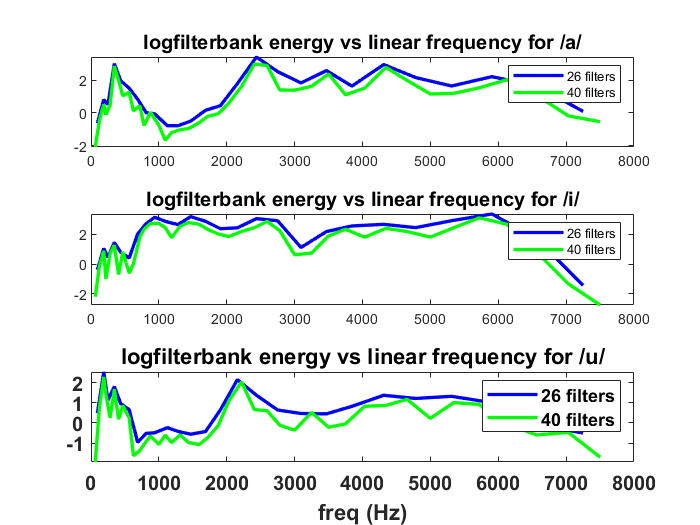


figure;
subplot(3,1,1)
plot(logFfreq_a, logFout_a,'LineWidth',2,'color','b')
hold on
plot(logFfreq_a_40, logFout_a_40,'LineWidth',2,'color','g')
legend('26 filters','40 filters')

title('logfilterbank energy vs linear frequency for /a/', 'FontSize',12,'FontWeight','Bold')

subplot(3,1,2)
plot(logFfreq_i, logFout_i,'LineWidth',2,'color','b')
hold on
plot(logFfreq_i_40, logFout_i_40,'LineWidth',2,'color','g')
legend('26 filters','40 filters')
title('logfilterbank energy vs linear frequency for /i/', 'FontSize',12,'FontWeight','Bold')

subplot(3,1,3)
plot(logFfreq_u, logFout_u,'LineWidth',2,'color','b')
hold on
plot(logFfreq_u_40, logFout_u_40,'LineWidth',2,'color','g')
title('logfilterbank energy vs linear frequency for /u/', 'FontSize',12,'FontWeight','Bold')
xlabel('freq (Hz)', 'FontSize',12,'FontWeight','Bold')
legend('26 filters','40 filters')
set(gca,'FontSize',12,'FontWeight','Bold')


temp=1;

